# The shape of the OTS model and the heterogeneity effect

## Main conclusions

- **Most of the normalization over orientation channels can account for the heterogeneity effect. The shape and whether it is orientation tuned does not really matter. **

- **Normalization by contrast energy can also capture the heterogeneity effect. **

% access to all folders
s0_add_paths

## Different types of OTS filters

- Elipse-oriTune:

- Round-oriTune

- Elipse-nonTune

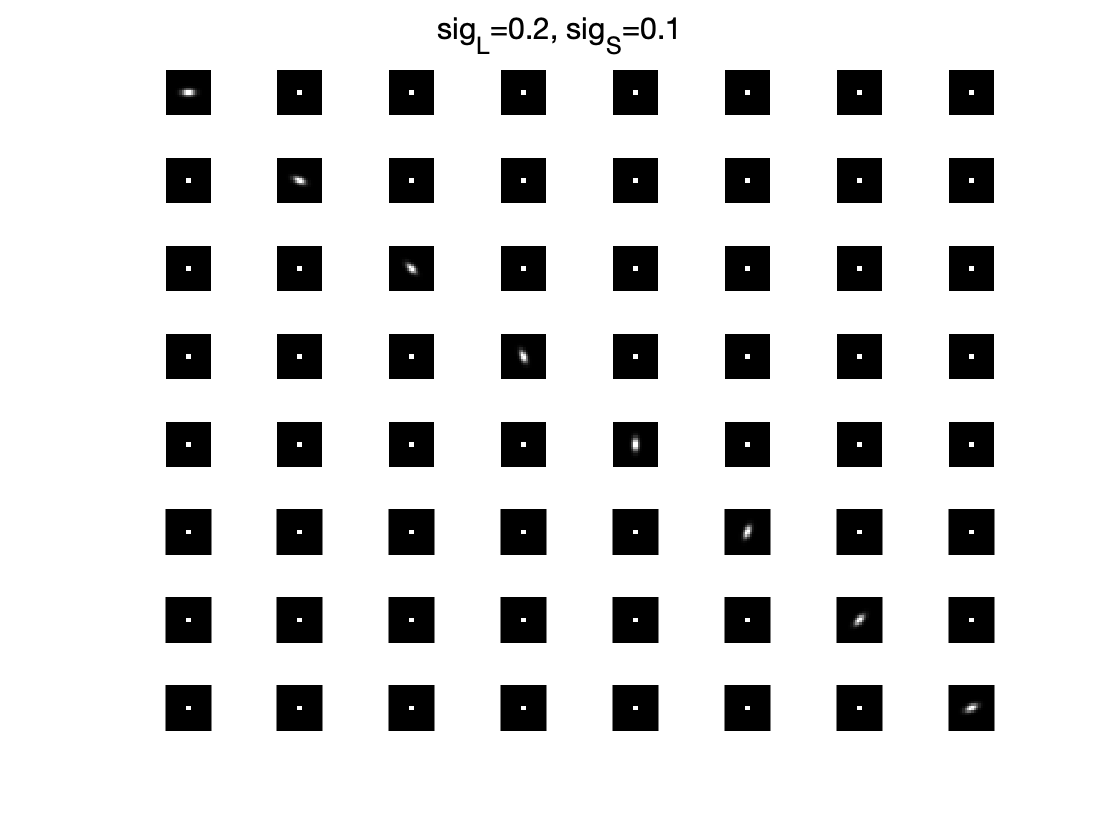

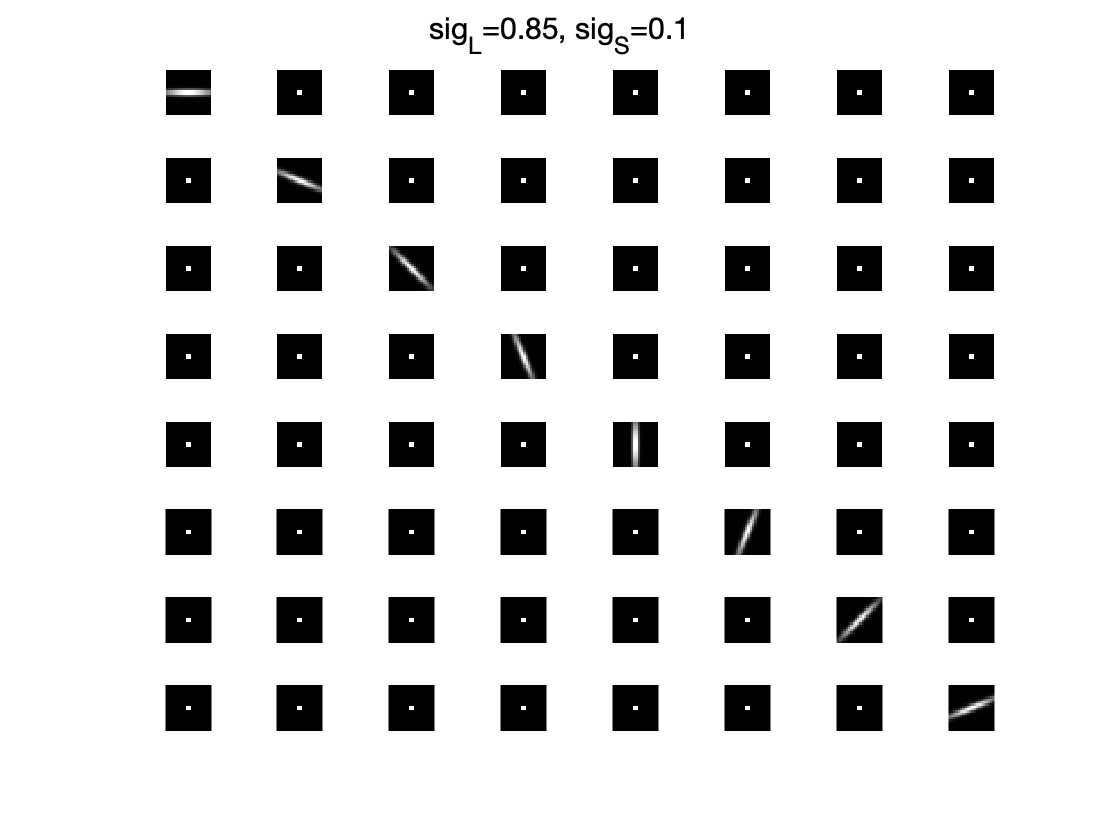

ans = NaN

OTSFilters('Elipse-oriTune', 'Filters')

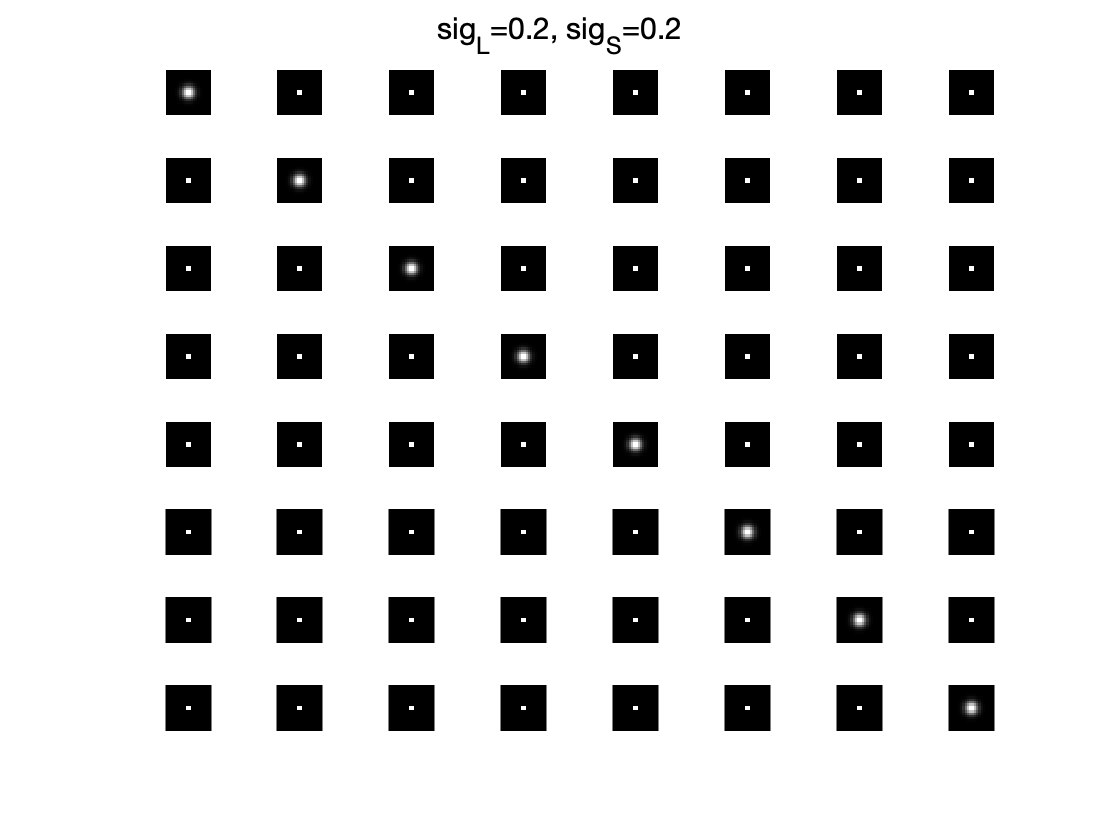

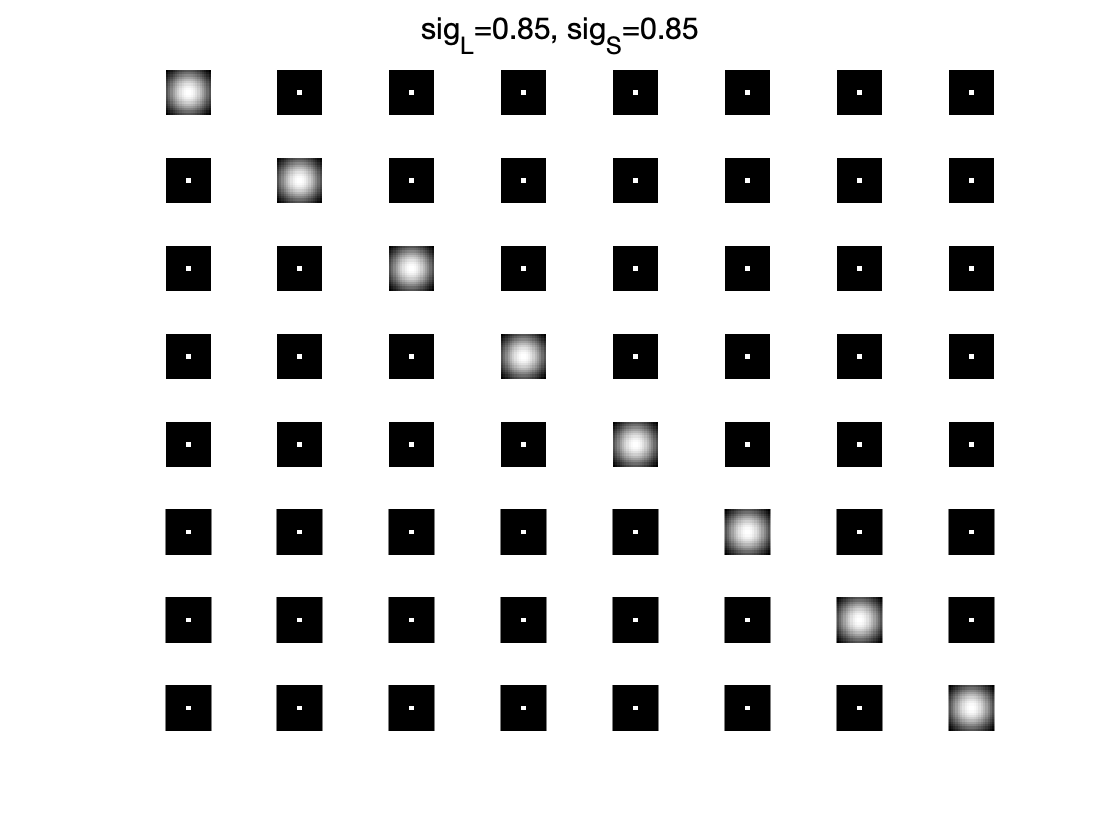

ans = NaN

OTSFilters('Round-oriTune', 'Filters')

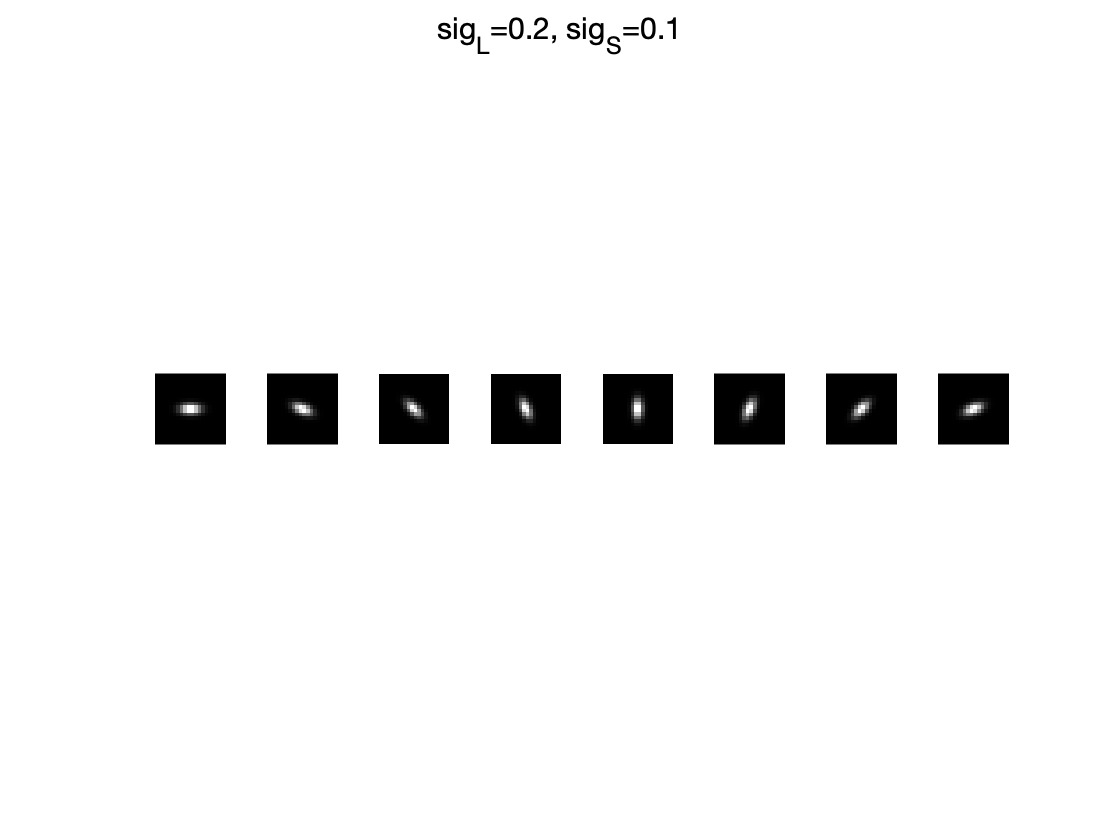

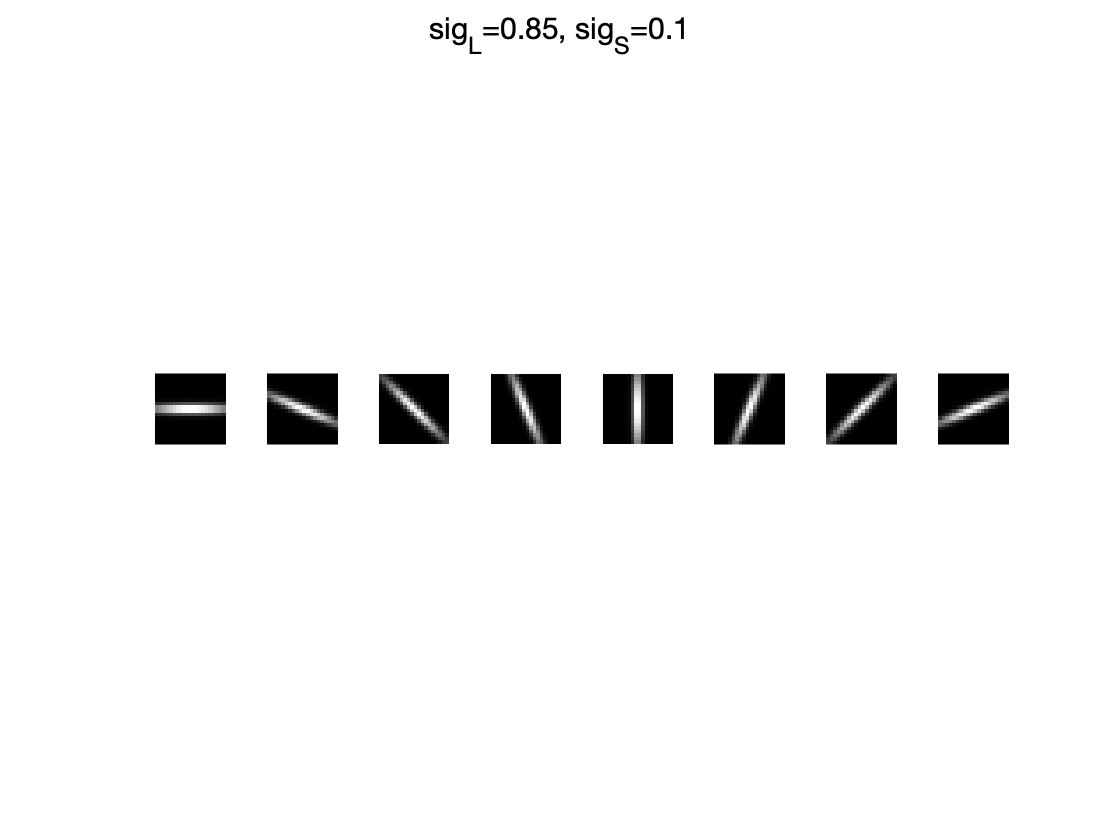

ans = NaN

OTSFilters('Elipse-nonTune', 'Filters')

## Get the simulation data 

All simulations are done in a grid search manner, the parameters we used

w_Lst    = [.1, 1, 10, 100, 10000, 1e6];
sig_Lst  = linspace(.1, .85, 5);

% get data
OTSFilters('Elipse-oriTune', 'Get data')

..........

..........

..........

..........

..........


ans = NaN

OTSFilters('Round-oriTune', 'Get data')

..........

..........

..........

..........

..........


ans = NaN

OTSFilters('Elipse-nonTune', 'Get data')

..........

..........

..........

..........

..........


ans = NaN

## Compares normalization of new filters and the benchmark

**Conclusion: The shape of the filters does not really matter.**

The orientation tune surround model :


$$d(x,y,\theta) =  \frac{E(x,y,\theta)}{1 + Z(x,y,\theta)} $$



$$s = \frac{1}{N_x \times N_y \times N_{\theta}}\sum_{x,y,\theta} d(x,y,\theta)$$


where 


$$Z(x,y,\theta) =\frac{1}{N_x \times N_y \times N_{\theta}} \sum_{x',y',\theta'} F(x',y',\theta')E(x-x',y-y',\theta-\theta')$$


The model with no orientation tunning


$$Z(x,y,\theta) = \frac{1}{N_x \times N_y } \sum_{x',y'} F(x',y',\theta)E(x-x',y-y',\theta)$$


The benchmark is what we have used in the previous paper $\sigma_{\mathrm{L}} =0\ldotp 85,\sigma_{\mathrm{S}} =0\ldotp 1$. 

We hope to progressively answer the following questions by comparison. 

#### Do different filters return different BOLD predictions (without gain $g$ and Exponential $n$)?

Answer is: The shape of the fitler matters but not a lot.

ds = 1; roi = 1;
BOLD_tar = dataloader(stdnormRootPath, 'BOLD_target','target', ds, roi);
viz = ColorPalette();
curvy   = [  .4,  .4,  .4] + .1;
grating = [  .6,  .6,  .6] + .1;
colors = {curvy, grating, curvy, grating};
nW = length(w_Lst);
nS = length(sig_Lst);
switch ds
    case 1; tar_ind = [1:5;6:10;15,16,3,17,18;11,12,8,13,14]; N=18;
    case 4; tar_ind = [9:12, 26, 28:39];
end

% Does sigma_L affect the normalization, and thus BOLD predictions?
[sim, ben] = OTSFilters('Elipse-oriTune', 's');

return scaled simulation and benchmark for
   w in
   1.0e+06 *

    0.0000    0.0000    0.0000    0.0001    0.0100    1.0000

   sigma in
    0.1000    0.2875    0.4750    0.6625    0.8500



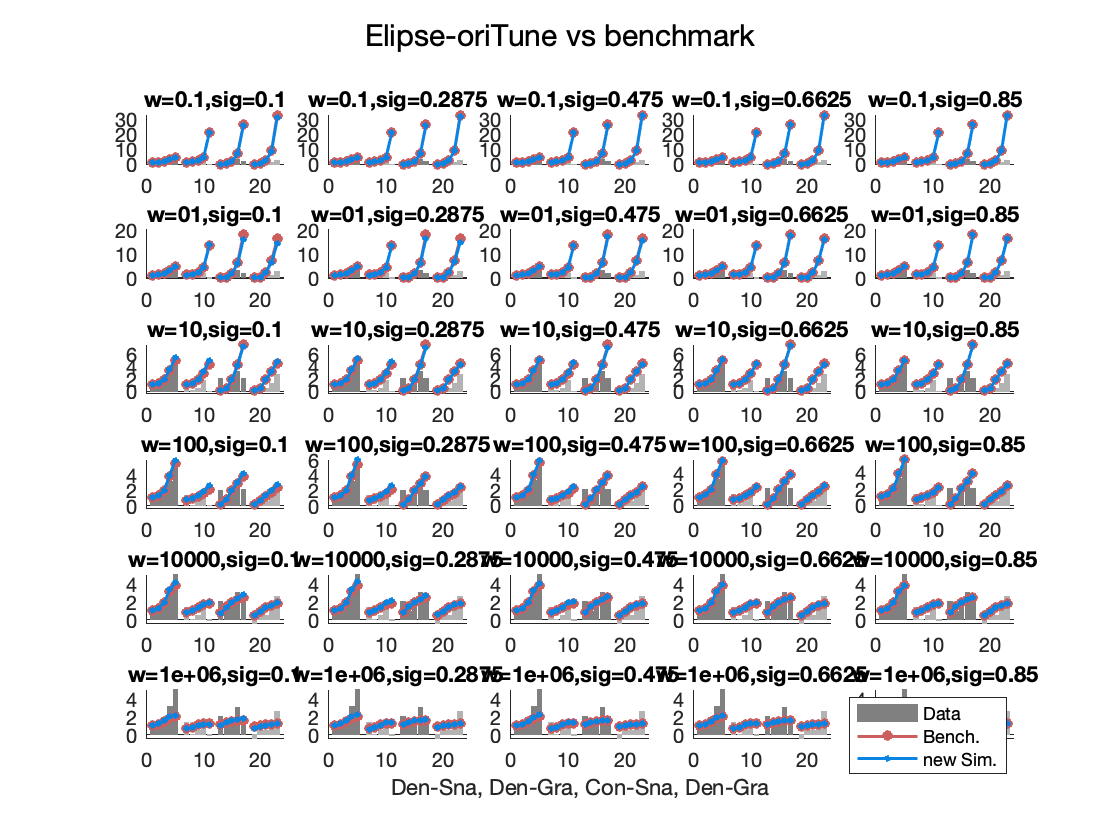

% visualize the comparison
figure();
for i = 1:length(w_Lst)
    for j = 1:length(sig_Lst)
        subplot(nW, nS, (i-1)*nS+j)
        hold on
        for k = 1:size(tar_ind, 1)
            ind = tar_ind(k, :);
            bar(6*k-5:6*k-1, BOLD_tar(ind)./BOLD_tar(1),...
                'Facecolor', colors{k},...
                'EdgeColor', colors{k});
            plot(6*k-5:6*k-1, squeeze(ben(i, ind)),...
                '-o', 'MarkerSize', 4,...
                'MarkerEdgeColor', viz.Red, ...
                'MarkerFaceColor', viz.Red,...
                'LineWidth', 1.5,...
                'Color', viz.Red);
            plot(6*k-5:6*k-1, squeeze(sim(i, j, ind)),...
                '-o', 'MarkerSize', 2,...
                'MarkerEdgeColor', viz.Blue, ...
                'MarkerFaceColor', viz.Blue,...
                'LineWidth', 1.5,...
                'Color', viz.Blue);
            title(sprintf('w=%02g,sig=%02g', w_Lst(i), sig_Lst(j)))
            if (i == nW) && (j==3)
                xlabel('Den-Sna, Den-Gra, Con-Sna, Den-Gra')
            end
        end
    end
end
legend('Data', 'Bench.', 'new Sim.')
sgtitle('Elipse-oriTune vs benchmark')

hold off

% Does round filter affect the normalization, and thus BOLD predictions?
[sim, ben] = OTSFilters('Round-oriTune', 's');

return scaled simulation and benchmark for
   w in
   1.0e+06 *

    0.0000    0.0000    0.0000    0.0001    0.0100    1.0000

   sigma in
    0.1000    0.2875    0.4750    0.6625    0.8500



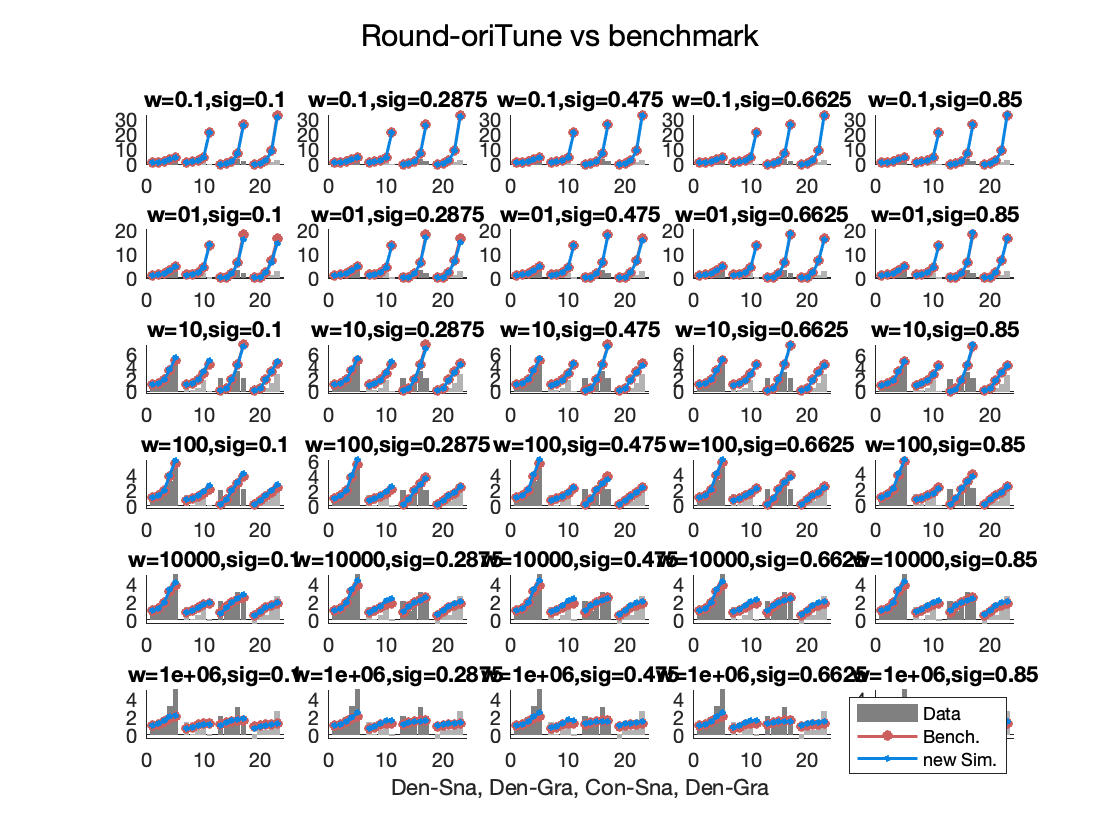

% visualize the comparison
figure();
for i = 1:length(w_Lst)
    for j = 1:length(sig_Lst)
        subplot(nW, nS, (i-1)*nS+j)
        hold on
        for k = 1:size(tar_ind, 1)
            ind = tar_ind(k, :);
            bar(6*k-5:6*k-1, BOLD_tar(ind)./BOLD_tar(1),...
                'Facecolor', colors{k},...
                'EdgeColor', colors{k});
            plot(6*k-5:6*k-1, squeeze(ben(i, ind)),...
                '-o', 'MarkerSize', 4,...
                'MarkerEdgeColor', viz.Red, ...
                'MarkerFaceColor', viz.Red,...
                'LineWidth', 1.5,...
                'Color', viz.Red);
            plot(6*k-5:6*k-1, squeeze(sim(i, j, ind)),...
                '-o', 'MarkerSize', 2,...
                'MarkerEdgeColor', viz.Blue, ...
                'MarkerFaceColor', viz.Blue,...
                'LineWidth', 1.5,...
                'Color', viz.Blue);
            title(sprintf('w=%02g,sig=%02g', w_Lst(i), sig_Lst(j)))
            if (i == nW) && (j==3)
                xlabel('Den-Sna, Den-Gra, Con-Sna, Den-Gra')
            end
        end
    end
end
legend('Data', 'Bench.', 'new Sim.')
sgtitle('Round-oriTune vs benchmark')

hold off

% Does round filter affect the normalization, and thus BOLD predictions?
[sim, ben] = OTSFilters('Elipse-nonTune', 's');

return scaled simulation and benchmark for
   w in
   1.0e+06 *

    0.0000    0.0000    0.0000    0.0001    0.0100    1.0000

   sigma in
    0.1000    0.2875    0.4750    0.6625    0.8500



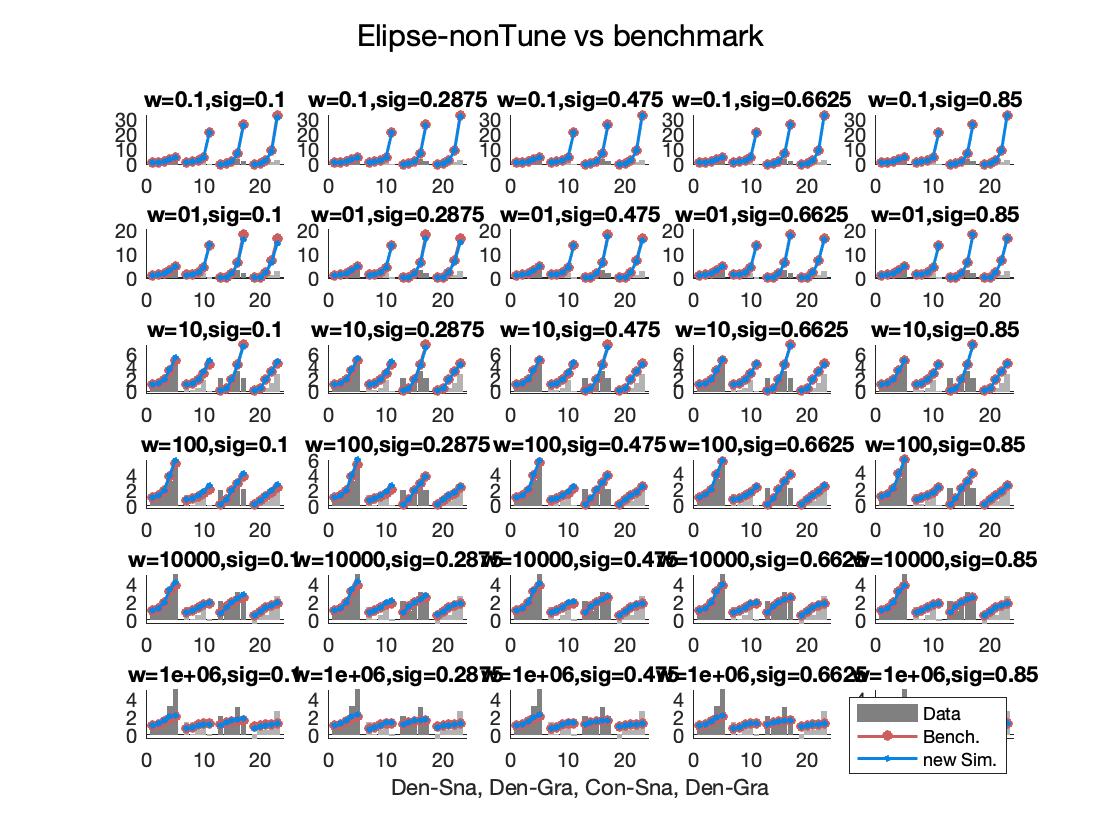

% visualize the comparison
figure();
for i = 1:length(w_Lst)
    for j = 1:length(sig_Lst)
        subplot(nW, nS, (i-1)*nS+j)
        hold on
        for k = 1:size(tar_ind, 1)
            ind = tar_ind(k, :);
            bar(6*k-5:6*k-1, BOLD_tar(ind)./BOLD_tar(1),...
                'Facecolor', colors{k},...
                'EdgeColor', colors{k});
            plot(6*k-5:6*k-1, squeeze(ben(i, ind)),...
                '-o', 'MarkerSize', 4,...
                'MarkerEdgeColor', viz.Red, ...
                'MarkerFaceColor', viz.Red,...
                'LineWidth', 1.5,...
                'Color', viz.Red);
            plot(6*k-5:6*k-1, squeeze(sim(i, j, ind)),...
                '-o', 'MarkerSize', 2,...
                'MarkerEdgeColor', viz.Blue, ...
                'MarkerFaceColor', viz.Blue,...
                'LineWidth', 1.5,...
                'Color', viz.Blue);
            title(sprintf('w=%02g,sig=%02g', w_Lst(i), sig_Lst(j)))
            if (i == nW) && (j==3)
                xlabel('Den-Sna, Den-Gra, Con-Sna, Den-Gra')
            end
        end
    end
end
legend('Data', 'Bench.', 'new Sim.')
sgtitle('Elipse-nonTune vs benchmark')

hold off

## Have a look at the contrast energy before summation

If all $d$s are all the same, it could be a mistake. But it is not.

The shape of filters matters but whether it is orientation tune does not.

..........

..........

..........


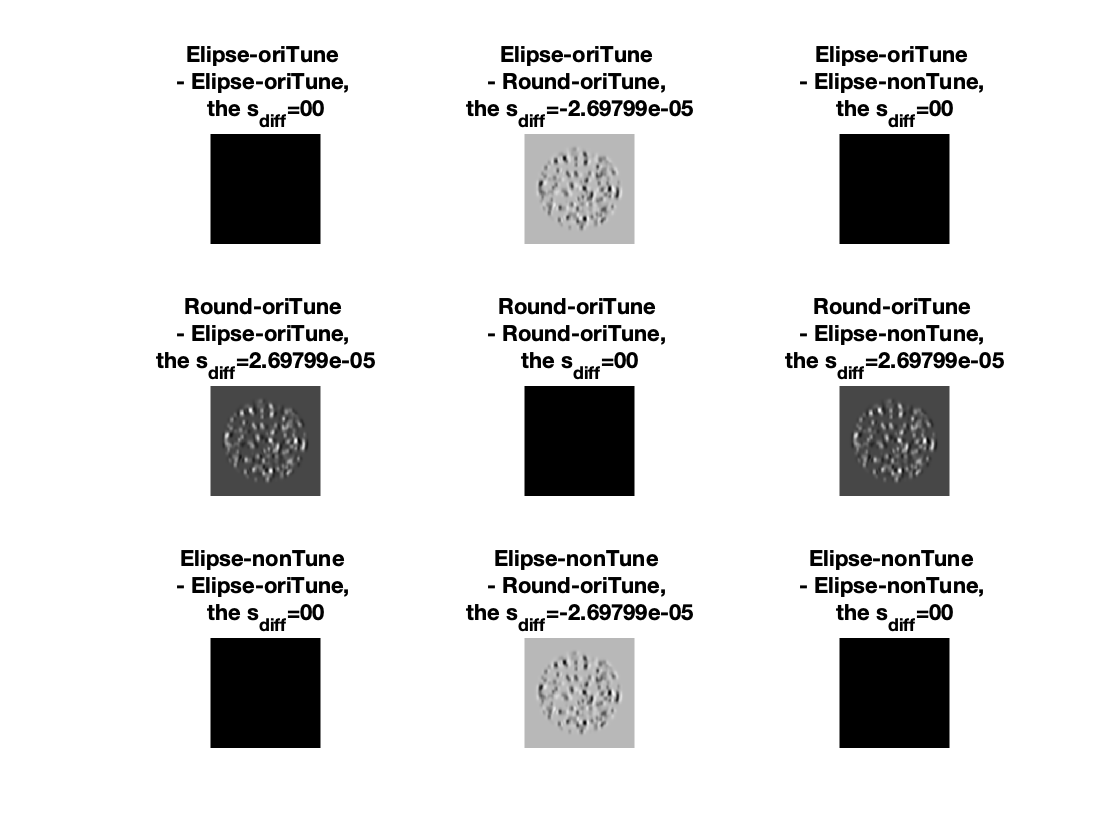

ans = NaN

OTSFilters('Compare ds');

## Does it mean all we need is the normalization at the orientaiton channel?

A general form of the normalization we implemented so far can be consider a function of $E$, 


$$Z(x,y,\theta) =f(E(x,y,\theta)) $$
 

Maybe we want to know, if $E$ itself as a normalization works?

**Normalization by E also accounts for the heterogeneity effect. **

[sim, ben] = OTSFilters('Norm by CE', 's');

return scaled simulation and benchmark for
   w in
   1.0e+06 *

    0.0000    0.0000    0.0000    0.0001    0.0100    1.0000



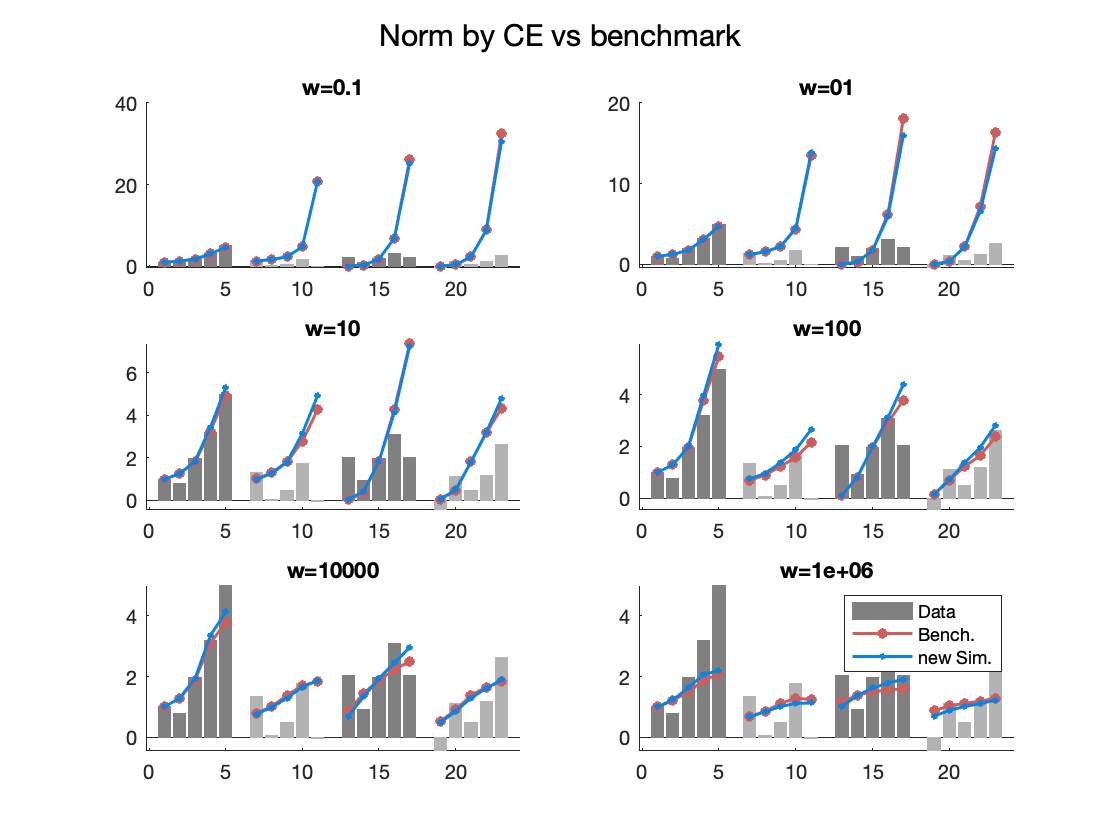

% visualize the comparison
figure();
for i = 1:length(w_Lst)
    subplot(3, 2, i)
    hold on
    for k = 1:size(tar_ind, 1)
        ind = tar_ind(k, :);
        bar(6*k-5:6*k-1, BOLD_tar(ind)./BOLD_tar(1),...
            'Facecolor', colors{k},...
            'EdgeColor', colors{k});
        plot(6*k-5:6*k-1, squeeze(ben(i, ind)),...
            '-o', 'MarkerSize', 4,...
            'MarkerEdgeColor', viz.Red, ...
            'MarkerFaceColor', viz.Red,...
            'LineWidth', 1.5,...
            'Color', viz.Red);
        plot(6*k-5:6*k-1, squeeze(sim(i, ind)),...
            '-o', 'MarkerSize', 2,...
            'MarkerEdgeColor', viz.Blue, ...
            'MarkerFaceColor', viz.Blue,...
            'LineWidth', 1.5,...
            'Color', viz.Blue);
        title(sprintf('w=%02g', w_Lst(i)))
        if (i == nW) && (j==3)
            xlabel('Den-Sna, Den-Gra, Con-Sna, Den-Gra')
        end
    end
end
legend('Data', 'Bench.', 'new Sim.')
sgtitle('Norm by CE vs benchmark')

hold off

## Let's run a simple example

First we generate two vectors:

E_Snake = [1/8, ....1/8] 

E_Grating = [h/8, ..., 1-7*h/8, h/8]

h here controls the degree of heterogenity. 



mean(E_Sna) == mean(E_Gra)

ans = logical
   0


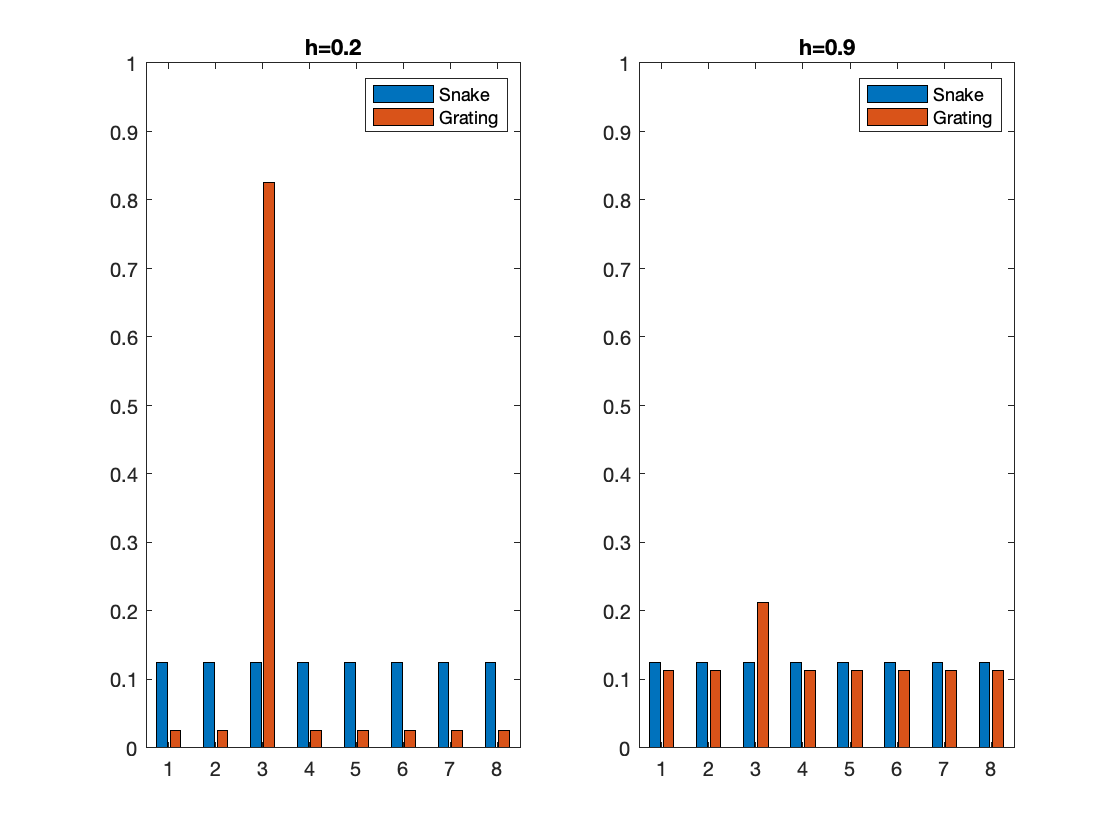

figure();
subplot(1, 2, 1)
h = .2; nT = 8;
E_Sna = ones(nT, 1)/nT;
E_Gra  = ones(nT, 1)*h/nT;
E_Gra(3) = 1 - h*(nT-1)/nT;
bar(1:nT, [E_Sna, E_Gra])
legend('Snake', 'Grating')
title(sprintf('h=%2g', h))
ylim([0,1])
subplot(1, 2, 2)
h = .9; nT = 8;
E_Sna = ones(nT, 1)/nT;
E_Gra  = ones(nT, 1)*h/nT;
E_Gra(3) = 1 - h*(nT-1)/nT;
bar(1:nT, [E_Sna, E_Gra])
legend('Snake', 'Grating')
title(sprintf('h=%2g', h))
ylim([0,1])

Then we pass two vectors through the following function


$$d(\theta) = \frac{E(\theta)}{1 + w E(\theta)} $$



$$s  = \frac{1}{N_{\theta}}\sum_\theta d(\theta)$$


The results suggest that normalization by contrast energy the gratings will always predict a lower response than the snakes. 

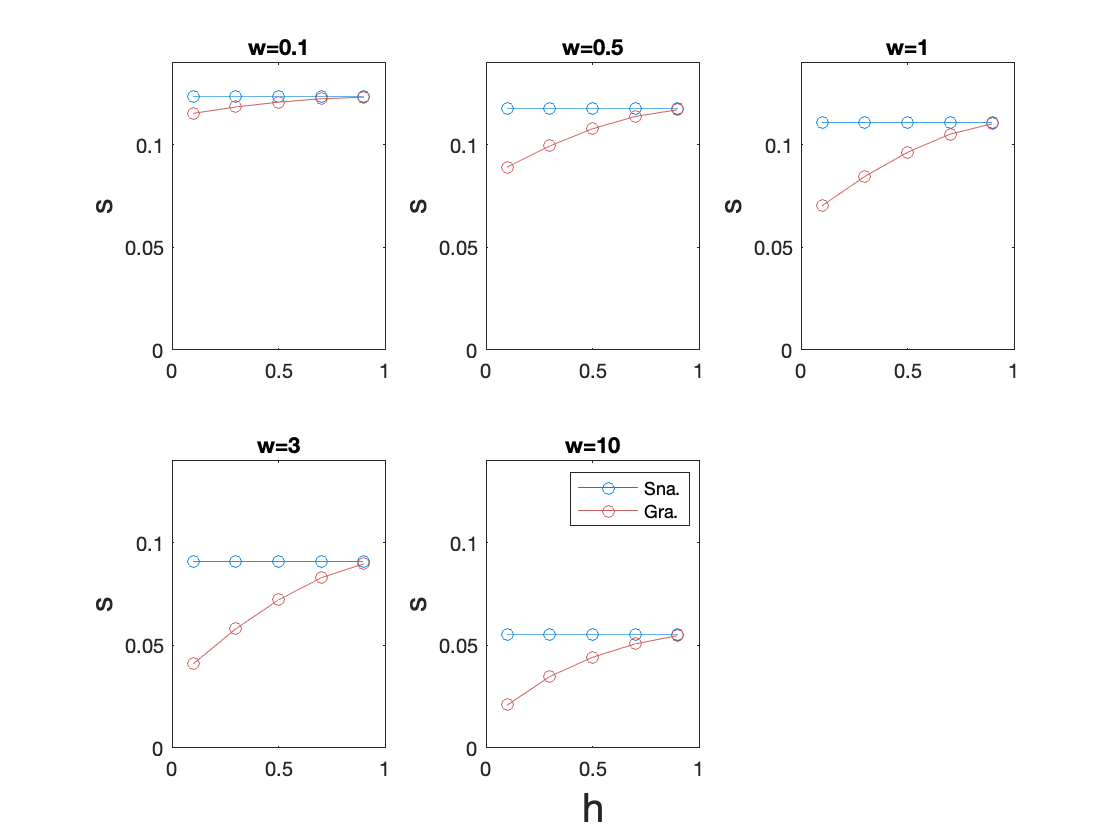

hs = linspace(.1, .9, 5); nH = length(hs);
ws = [.1, .5, 1, 3, 10];  nW = length(ws);

s_outcomes = nan(nW, nH, 2);
for i = 1:nW
    for j = 1:nH
        w = ws(i); h = hs(j);
        E_Sna = ones(nT, 1)/nT;
        d_Sna = E_Sna ./ (1 + w*E_Sna);
        s_Sna = mean(d_Sna);
        s_outcomes(i,j,1) = s_Sna;
        
        E_Gra  = ones(nT, 1)*h/nT;
        E_Gra(3) = 1 - h*(nT-1)/nT;
        d_Gra = E_Gra ./ (1 + w*E_Gra);
        s_Gra = mean(d_Gra);
        s_outcomes(i,j,2) = s_Gra;
    end
end

figure; 
for i = 1:nW
    subplot(2, 3, i)
    plot(hs, s_outcomes(i, :, 1), ...
        'o-', 'Color', viz.Blue)
    hold on 
    plot(hs, s_outcomes(i, :, 2), ...
        'o-', 'Color', viz.Red)
    ylim([0, .14])
    ylabel('s', "FontSize", 15)
    title(sprintf('w=%g', ws(i)))
end
legend('Sna.', 'Gra.')
xlabel('h', 'FontSize', 20)

hold off 